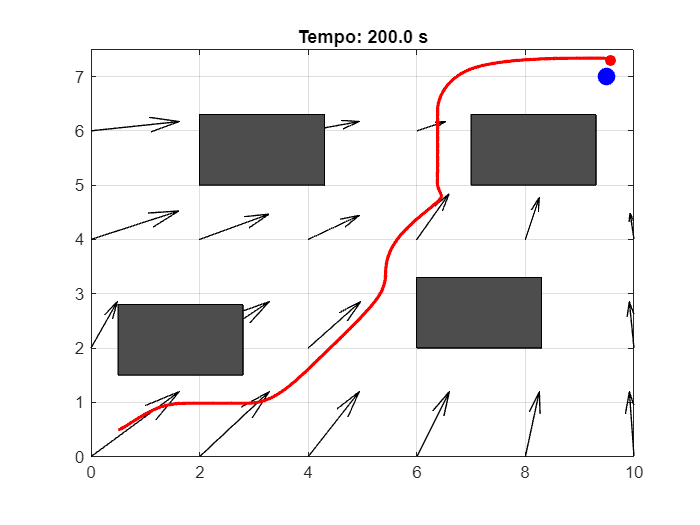



clc;
clear;
close all;

% Parametri
k_att = 2;
k_rep = 2.5;
rho_0 = 1.5;
v_max = 0.1;
omega_max = pi/4;
dt = 0.1;
threshold = 0.1;

% Posa iniziale e goal
x = 0.5; y = 0.5; theta = 0;
goal = [9.5, 7];
%ostacoli 
obstacles = [
    0.5, 1.5, 2.30, 1.30;
    6, 2, 2.30, 1.30;
    2, 5, 2.30, 1.30;
    7, 5, 2.30, 1.30
];

% Inizializza percorso
path_x = x;
path_y = y;

% Griglia per visualizzare campo
[x_grid, y_grid] = meshgrid(0:2:10, 0:2:7.5);
U = zeros(size(x_grid));
V = zeros(size(y_grid));

% Calcola campo potenziale
for i = 1:numel(x_grid)
    p = [x_grid(i); y_grid(i)];
    F_att = k_att * (goal' - p);

    F_rep = [0; 0];
    for j = 1:size(obstacles,1)
        [d, grad_d] = distanza_rettangolo(p, obstacles(j,:));
        if d < rho_0 && d > 0
            F_rep = F_rep + k_rep * (1/d - 1/rho_0) * (1/d^2) * grad_d;
        end
    end

    F = F_att + F_rep;
    U(i) = F(1);
    V(i) = F(2);
end

% Simulazione
t = 0;
v_log = [];
omega_log = [];
t_log = [];
while norm([x; y] - goal') > threshold && t < 200
    p = [x; y];
    F_att = k_att * (goal' - p);

    F_rep = [0; 0];
    for j = 1:size(obstacles,1)
        [d, grad_d] = distanza_rettangolo(p, obstacles(j,:));
        if d < rho_0 && d > 0
            F_rep = F_rep + k_rep * (1/d - 1/rho_0) * (1/d^2) * grad_d;
        end
    end

    F = F_att + F_rep;
    theta_desired = atan2(F(2), F(1));
    error_theta = wrapToPi(theta_desired - theta);
    
    omega = max(-omega_max, min(omega_max, 1.5 * error_theta));
    v = v_max * exp(-abs(error_theta)); % rallenta se troppo disallineato

    v_log(end+1) = v;
    omega_log(end+1) = omega;
    t_log(end+1) = t;

    % Aggiorna posa
    x = x + v * cos(theta) * dt;
    y = y + v * sin(theta) * dt;
    theta = wrapToPi(theta + omega * dt);

    % Salva percorso
    path_x(end+1) = x;
    path_y(end+1) = y;
    t = t + dt;
        
    % Visualizza
    if mod(round(t/dt), 10) == 0
        figure(1); clf;
        quiver(x_grid, y_grid, U, V, 'k'); hold on;
        for k = 1:size(obstacles,1)
            rectangle('Position', obstacles(k,:), 'FaceColor', [0.3 0.3 0.3 0.5], 'EdgeColor', 'k');
        end
        plot(path_x, path_y, 'r-', 'LineWidth', 2);
        plot(x, y, 'ro', 'MarkerFaceColor', 'r');
        plot(goal(1), goal(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
        title(sprintf('Tempo: %.1f s', t));
        axis equal; grid on;
        xlim([0 10]); ylim([0 7.5]);
        drawnow;
    end
end

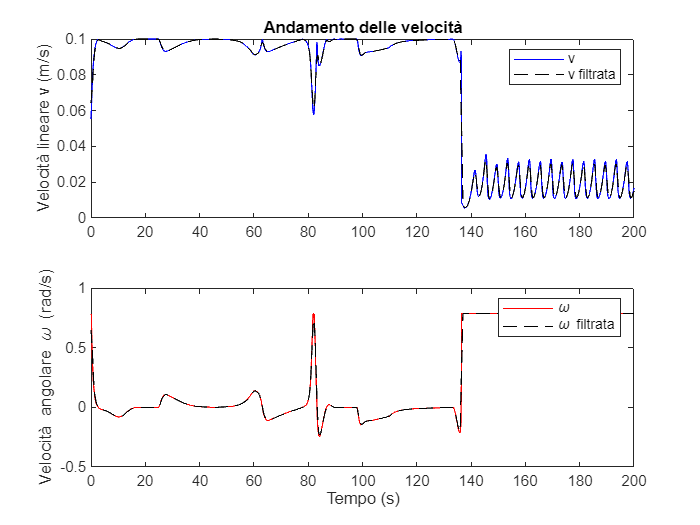

v_log_smooth = movmean(v_log, 10);
omega_log_smooth = movmean(omega_log, 10);

% Plot finale
figure;

subplot(2,1,1);
plot(t_log, v_log, 'b', t_log, v_log_smooth, '--k');
title('Andamento delle velocità');
ylabel('Velocità lineare v (m/s)');
legend('v', 'v filtrata');

subplot(2,1,2);
plot(t_log, omega_log, 'r', t_log, omega_log_smooth, '--k');
xlabel('Tempo (s)');
ylabel('Velocità angolare \omega (rad/s)');
legend('\omega', '\omega filtrata');



% Funzione distanza e gradiente continuo
function [d, grad_d] = distanza_rettangolo(p, rect)
    x = p(1); y = p(2);
    rx = rect(1); ry = rect(2); w = rect(3); h = rect(4);

    dx = max([rx - x, 0, x - (rx + w)]);
    dy = max([ry - y, 0, y - (ry + h)]);
    d = hypot(dx, dy);

    if d == 0
        grad_d = [0; 0];
    else
        px = min(max(x, rx), rx + w);
        py = min(max(y, ry), ry + h);
        grad_d = [(x - px); (y - py)] / (d + eps);
    end
end


